# Ingenuity copter

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

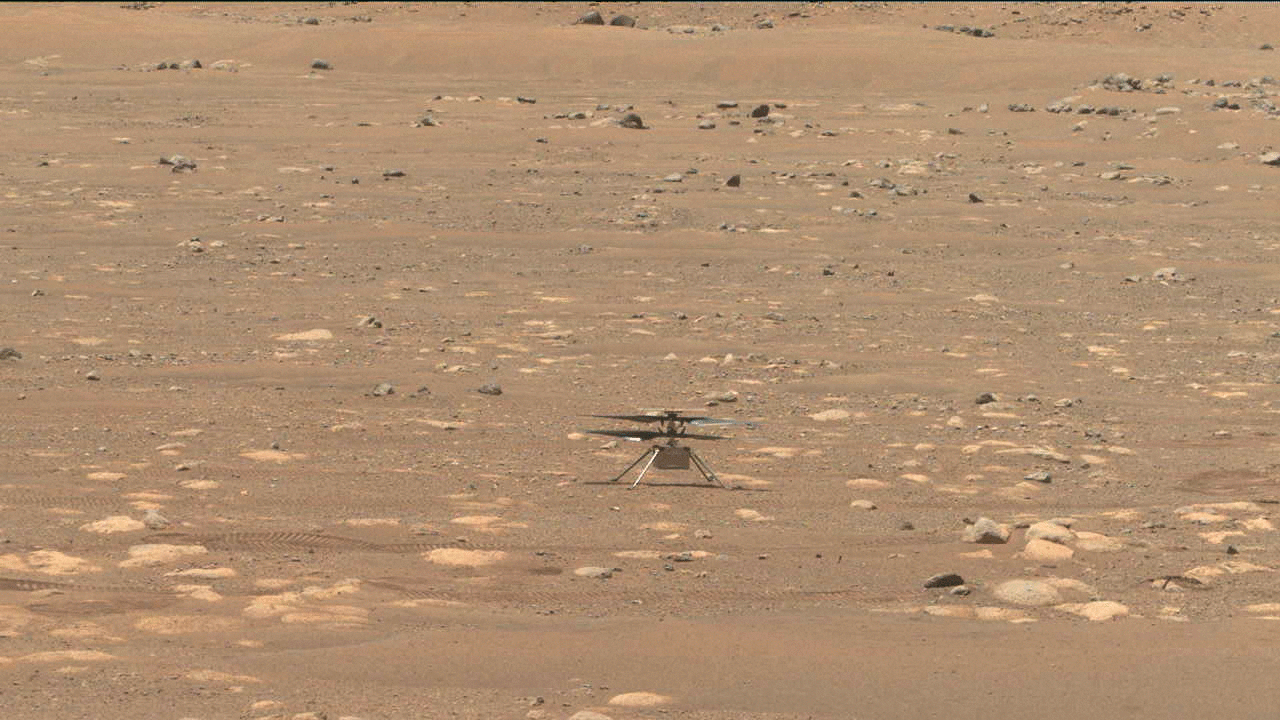

Ingenuity copter blades start to spin, credit: [NASA/JPL-Caltech/ASU](https://www.jpl.nasa.gov/missions/ingenuity)

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## First section

clear

syms F d m g rho
syms uF ud um ug urho
syms M L T
syms Fb db mb gb rhob

M = m

$$M = m$$

L = d

$$L = d$$

T = sqrt(L/g)

$$T = \sqrt{\frac{d}{g}}$$

Fb = F*T^2/M/L

$$Fb = \frac{F}{g\,m}$$

db = d/L

$$db = 1$$

mb = m/M

$$mb = 1$$

gb = g*T^2/L

$$gb = 1$$

rhob = rho*L^3/M

$$rhob = \frac{d^{3}\,\rho }{m}$$

Fb only depends on rhob (which in this case is pretty much d)

Fb = phi( rhob )

F = gm*phi( d^3*rho/m )

Perform experiment on earth (Simulink rotor block)

Rho = 1.2

M = 1.5 kg

d = 1cm..10m

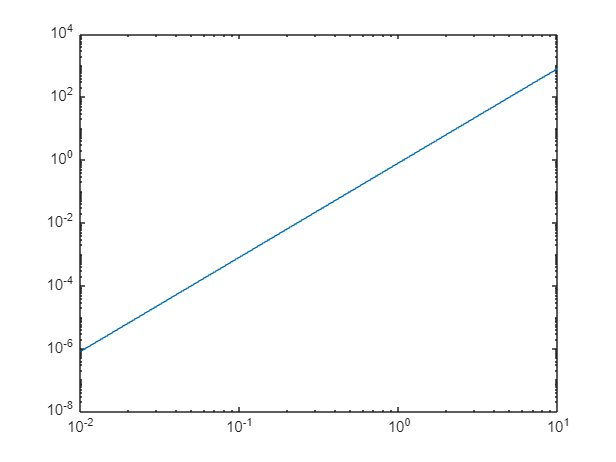

rho = 1.2;
m = 1.5;
d = logspace(-2,1,100);
rhob = d.^3*rho/m;
loglog(d,rhob)

Get the Thrust vs D

Apply that on Mars

[⇦ Return to the navigation page](matlab:open('./Overview.html'))

Copyright 2023 The MathWorks™, Inc